# Uso de la función wsa_cartto2nautfrom

Esta función convierte direcciones y distribuciones direccionales expresadas en convención cartesiana-hacia a convención náutica-desde.

La conversión aplicada corresponde a:


$$\theta_{naut} = mod(270 - \theta_{cart}, 360)$$


 donde:

- Convención cartesiana-hacia:

            - ángulos medidos desde el eje X positivo

            - sentido antihorario

            - dirección "hacia" donde viaja el oleaje

- Convención náutica-desde:

            - ángulos medidos desde el norte

            - sentido horario

            - dirección "desde" donde proviene el oleaje

Por defecto, las siguientes funciones del toolbox brindan los resultados con angulos medidos en la convención cartesiana-hacia:

- wsa_dirspectrum

- wsa_directional_parameters

La función detecta automáticamente el tipo de struct que se esta pasando.

## Datos de entrada

Para mostrar el uso de la función, en la carpeta *\toolbox\example_data* se colocó un struct con datos reales de una campaña de medición de AWAC. Para mas información acerca del 

data = load('burst_data.mat');

Para el ejemplo se estimó el espectro direccional basado en AST y velocidades horizontales, empleando el metodo SUV. Para mas información de los datos de entrada y el cálculo de espectros direccionales, ver *using_wsa_dirspectrum.mlx*.

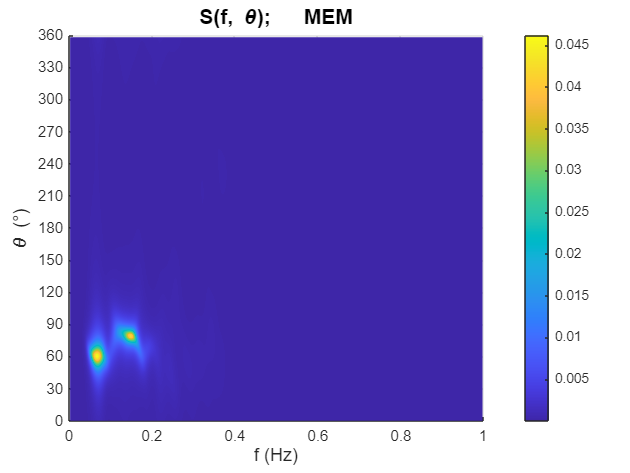

AST = data.burst_data.processed.ast(:, 1);
U = data.burst_data.processed.velocity_enu(:, 1);
V = data.burst_data.processed.velocity_enu(:, 2);

fs = data.burst_data.general.fs;
ast_mean = data.burst_data.general.ast_mean;
cell_position = data.burst_data.general.cell_position;
mounting_height = data.burst_data.general.mounting_height;

h   = ast_mean + mounting_height;
z_v = cell_position - ast_mean;

[out_DirSpec, info_DirSpec] = wsa_dirspectrum(AST, U, V, fs, 'SUV', ...
                                             'z_v', z_v, ...
                                             'h', h);

f = out_DirSpec.MEM.f;
theta = out_DirSpec.MEM.theta;
E = out_DirSpec.MEM.E;
S = out_DirSpec.MEM.S;
a1 = out_DirSpec.MEM.coeffs.a1;
b1 = out_DirSpec.MEM.coeffs.b1;
a2 = out_DirSpec.MEM.coeffs.a2;
b2 = out_DirSpec.MEM.coeffs.b2;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'MEM';      %Para el título unicamente.
plot_DirSpec(f, theta, E, xdir_out, DirMethod)


out_Dir_Params = wsa_directional_parameters(out_DirSpec.MEM) 

out_Dir_Params = struct with fields:
                       fp: 0.0684
                       Tp: 14.6286
                    DirTp: 61.3594
                    SprTp: 28.3475
                  MeanDir: 69.1037
               MeanSpread: 40.2209
               f_mean_dir: [511×1 double]
                f_dir_spr: [511×1 double]
                       m0: 0.1144
                    a1_wa: 0.2688
                    b1_wa: 0.7040
                    R1_wa: 0.7536
              band_limits: [0.0020 0.9980]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0.0020 0.9980]
           source_spectra: [1×1 struct]


## Conversión de espectro direccional a convención Nautica - Desde

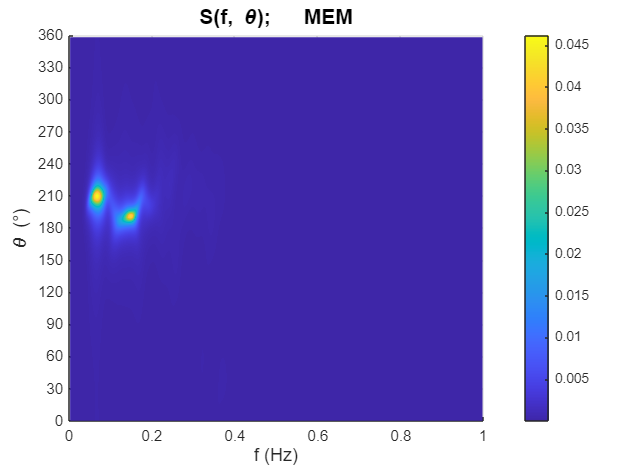

out_DirSpec_NautFrom = wsa_cartto2nautfrom(out_DirSpec);

f = out_DirSpec_NautFrom.MEM.f;
theta = out_DirSpec_NautFrom.MEM.theta;
E = out_DirSpec_NautFrom.MEM.E;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'MEM';      %Para el título unicamente.
plot_DirSpec(f, theta, E, xdir_out, DirMethod)

## Conversión de parámetros direccionales a convención Nautica - Desde

out_Dir_Params_NautFrom = wsa_cartto2nautfrom(out_Dir_Params)

out_Dir_Params_NautFrom = struct with fields:
                       fp: 0.0684
                       Tp: 14.6286
                    DirTp: 208.6406
                    SprTp: 28.3475
                  MeanDir: 200.8963
               MeanSpread: 40.2209
               f_mean_dir: [511×1 double]
                f_dir_spr: [511×1 double]
                       m0: 0.1144
                    a1_wa: 0.2688
                    b1_wa: 0.7040
                    R1_wa: 0.7536
              band_limits: [0.0020 0.9980]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0.0020 0.9980]
           source_spectra: [1×1 struct]
